**KURAMOTO ODE**

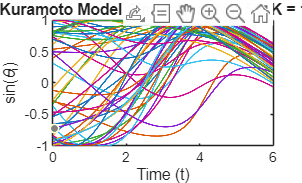

% ==========================
% (1) Set up trainig data
% ==========================
N = 50; K = 1.5; omega = rand(N, 1);	%constants 
occurences = 3000; h = 1/occurences;  
tspan = linspace(0, 6, occurences);     %set up tspan to point of synchronicity
dt = tspan(2) - tspan(1);
rng(51);
theta0 = -pi + 2*pi*rand(N, 1);

dtheta_dt = @(t, theta) omega + (K/N) * sum(sin(theta.' - theta), 2);
[t, theta_out] = ode45(dtheta_dt, tspan, theta0);

figure; plot(t, sin(theta_out), 'LineWidth', 1); 
xlabel('Time (t)'); ylabel('sin(\theta_i)'); 
title(sprintf('Kuramoto Model Simulation (N = %d, K = %.1f)', N, K)); 


% ==========================
% (2) Feature Engineering for Physics Informed Model
% ==========================
%Calculate numerical differentiation of theta:
dXdt = (theta_out(2:end,:) - theta_out(1:end-1,:))/h; 
Ytrain = reshape(dXdt, [], 1);

% Calculate order parameter variables for feature input vector:
theta_train = theta_out(1:occurences-1, :);
order_param = mean(exp(1i * theta_train), 2);
r = abs(order_param); psi = angle(order_param);
omega_matrix = repelem(omega, occurences-1, 1);
r_matrix = repmat(r, N, 1);

rel_phase = reshape(psi - theta_train, [], 1);

Xtrain = [omega_matrix, r_matrix, sin(rel_phase), cos(rel_phase)];

% ==========================
% (3) Regular ReLU NN
% ==========================
numFeatures = size(Xtrain, 2);
numOutputs = size(Ytrain, 2);

layers = [
    featureInputLayer(numFeatures, 'Normalization','zscore','Name','input')

    fullyConnectedLayer(32, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(32, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(numOutputs, 'Name', 'output')
]

layers =   10×1 Layer array with layers:

     1   'input'    Feature Input     51 features with 'zscore' normalization
     2   'fc1'      Fully Connected   64 fully connected layer
     3   'relu1'    ReLU              ReLU
     4   'fc2'      Fully Connected   64 fully connected layer
     5   'relu2'    ReLU              ReLU
     6   'fc3'      Fully Connected   64 fully connected layer
     7   'relu3'    ReLU              ReLU
     8   'fc4'      Fully Connected   50 fully connected layer
     9   'relu4'    ReLU              ReLU
    10   'output'   Fully Connected   50 fully connected layer

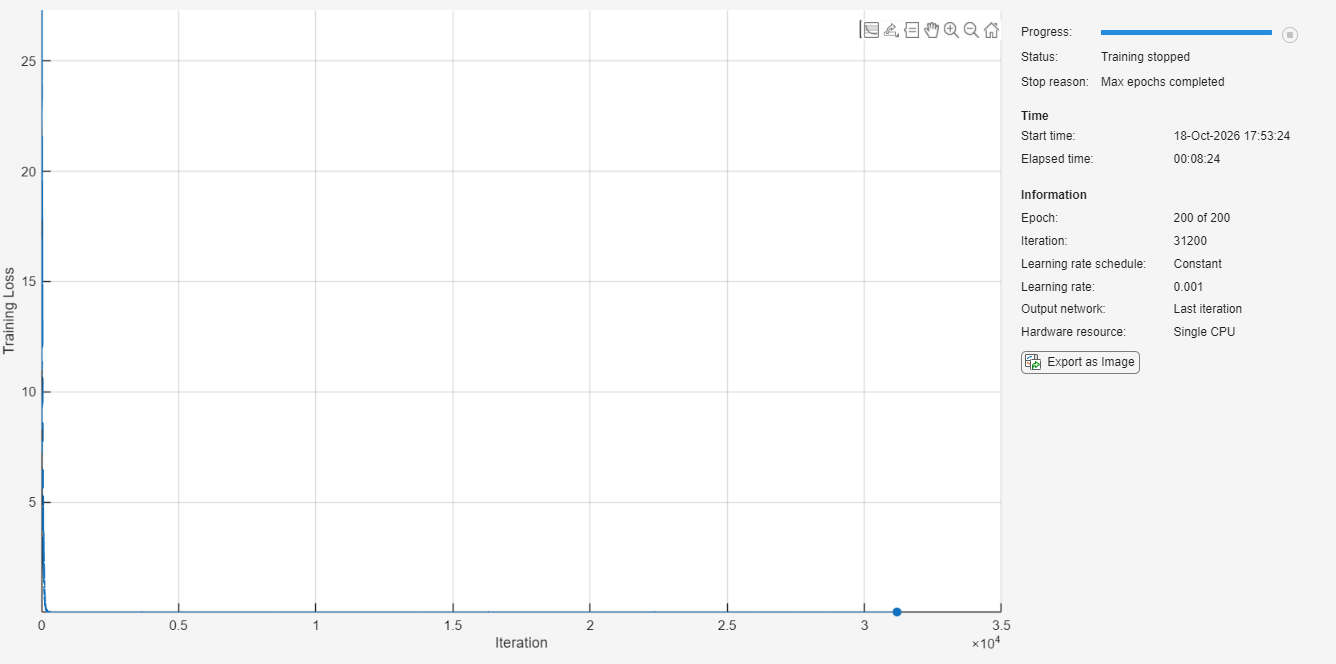


options = trainingOptions('adam', ...
    'MaxEpochs', 15, ...           
    'MiniBatchSize', 256, ...      
    'InitialLearnRate', 0.005, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');

trainedNet = trainnet(Xtrain, Ytrain, layers, "mse",options);

% ==========================
% (4.1) Explicit Euler - Validation 
% ==========================
fNN = zeros(occurences-1, N);
fNN(1, :) = theta_out(1, :); 

for i = 1:(occurences-2)
    order_param_I = mean(exp(1i * fNN(i, :)));
    rI = abs(order_param_I); psiI = angle(order_param_I);
    NN_Input_I = [ 
        omega, ...
        repmat(rI, N, 1), ...
        sin(psiI - fNN(i, :).'), ...
        cos(psiI - fNN(i, :).')
    ];

    fNN(i+1,:) = fNN(i,:) + dt .* predict(trainedNet, NN_Input_I).';
end %for

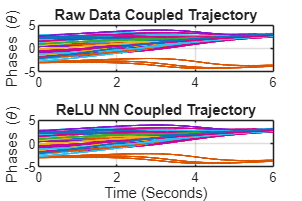

% ==========================================
% (5.1) Compare Data to NN:
% ==========================================
figure('Position', [100, 100, 900, 600]);

subplot(2, 1, 1);
plot(tspan(1:end-1), theta_out(1:end-1, :), 'LineWidth', 1.2);
title('Raw Data Coupled Trajectory');
ylabel('Phases (\theta)');
grid on;

subplot(2, 1, 2);
plot(tspan(1:end-1), fNN, 'LineWidth', 1.2);
title('ReLU NN Coupled Trajectory');
xlabel('Time (Seconds)');
ylabel('Phases (\theta)');
grid on;

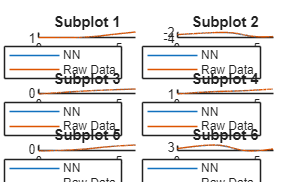

% ==========================================
% (5.2) Compare Data to NN - Individual:
% ==========================================
figure
hold on
p = tiledlayout(3,2);
ptitles = ['Subplot 1'
    'Subplot 2'
    'Subplot 3'  
    'Subplot 4'
    'Subplot 5'
    'Subplot 6'];
for i = 1:6
    nexttile;
    hold on;
    plot(tspan(1:occurences-1), fNN(1:occurences-1, i))
    plot(tspan(1:occurences-1), theta_out(1:occurences-1, i))
    legend('NN', 'Raw Data')
    title(ptitles(i, :))
    hold off;
end 
hold off

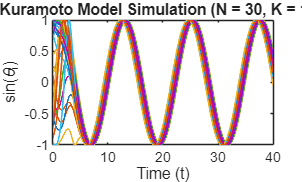

% ==========================
% (6.1) Validation - New Coupled System:
% ==========================
N_new = 30; K_new = 1.5; omega_new = rand(N_new, 1);	%constants 
occurences_new = 3000; h_new = 1/occurences_new;  
tspan_new = linspace(0, 40, occurences_new);     %set up tspan to point of synchronicity
dt_new = tspan_new(2) - tspan_new(1);
rng(52);
theta0_new = -pi + 2*pi*rand(N_new, 1);

dtheta_dt_new = @(t, theta) omega_new + (K_new/N_new) * sum(sin(theta.' - theta), 2);
[t_new, theta_out_new] = ode45(dtheta_dt_new, tspan_new, theta0_new);

figure; plot(t_new, sin(theta_out_new), 'LineWidth', 1); 
xlabel('Time (t)'); ylabel('sin(\theta_i)'); 
title(sprintf('Kuramoto Model Simulation (N = %d, K = %.1f)', N_new, K_new)); 

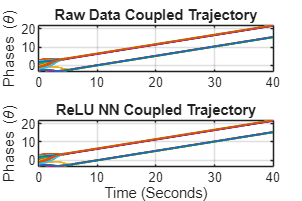


% ==========================
% (6.2) Explicit Euler - Validation:
% ==========================
fNN_new = zeros(occurences_new-1, N_new);
fNN_new(1, :) = theta_out_new(1, :); 

for i = 1:(occurences_new-2)
    order_param_I = mean(exp(1i * fNN_new(i, :)));
    rI = abs(order_param_I); psiI = angle(order_param_I);
    NN_Input_I = [ 
        omega_new, ...
        repmat(rI, N_new, 1), ...
        sin(psiI - fNN_new(i, :).'), ...
        cos(psiI - fNN_new(i, :).')
    ];

    fNN_new(i+1,:) = fNN_new(i,:) + dt_new .* predict(trainedNet, NN_Input_I).';
end %for

% ==========================================
% (7.1) Compare Data to NN:
% ==========================================
figure('Position', [100, 100, 900, 600]);

subplot(2, 1, 1);
plot(tspan_new(1:end-1), theta_out_new(1:end-1, :), 'LineWidth', 1.2);
title('Raw Data Coupled Trajectory');
ylabel('Phases (\theta)');
grid on;

subplot(2, 1, 2);
plot(tspan_new(1:end-1), fNN_new, 'LineWidth', 1.2);
title('ReLU NN Coupled Trajectory');
xlabel('Time (Seconds)');
ylabel('Phases (\theta)');
grid on;

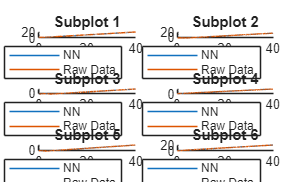


% ==========================================
% (7.2) Compare Data to NN - Individual:
% ==========================================
figure
hold on
p = tiledlayout(3,2);
ptitles = ['Subplot 1'
    'Subplot 2'
    'Subplot 3'  
    'Subplot 4'
    'Subplot 5'
    'Subplot 6'];
for i = 1:6
    nexttile;
    hold on;
    plot(tspan_new(1:occurences_new-1), fNN_new(1:occurences_new-1, i))
    plot(tspan_new(1:occurences_new-1), theta_out_new(1:occurences_new-1, i))
    legend('NN', 'Raw Data')
    title(ptitles(i, :))
    hold off;
end 
hold off

%%%%%%STORE NN COEFFICIENTS DATA
filename = "FitRNet_Storage_THETA.xlsx";
numLayers = size(trainedNet.Layers, 1) / 2;

for j = 1:numLayers
    if j == 1
        A = trainedNet.Layers(j*2).Weights ./ trainedNet.Layers(1).StandardDeviation;
        writematrix(A, filename,'Sheet', j, 'Range', 'A1')
    else 
        writematrix(trainedNet.Layers(j*2).Weights, filename,'Sheet', j, 'Range', 'A1')
    end %if 
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for j = 1:numLayers
    if j == 1
        A = trainedNet.Layers(j*2).Bias - (trainedNet.Layers(j*2).Weights * (trainedNet.Layers(1).Mean ./ trainedNet.Layers(1).StandardDeviation)');
        writematrix(A, filename,'Sheet', j, 'Range', 'A1')
    else
        writematrix(trainedNet.Layers(j*2).Bias, filename,'Sheet', j, 'Range', 'A1')
    end %if 
end %for 

%%%%%%STORE RAW DATA
filename = "FitRNet_Storage_RawData.xlsx";
writematrix(theta_out, filename,'Sheet', 1, 'Range', 'A1')
writematrix(t, filename,'Sheet', 2, 'Range', 'A1')

%%%%%%STORE OMEGA PARAMETER DATA
csvFile_rawdata = "FitRNet_Storage_OMEGA.csv";
writematrix(omega, csvFile_rawdata);
